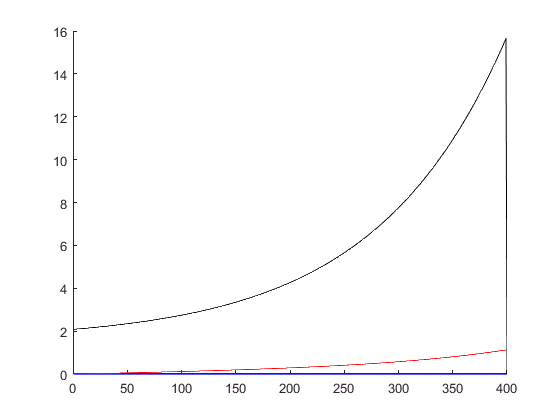

sup_x      = 0;   sup_z      = 0; 
ddot_sup_x = 0;   ddot_sup_z = 0.08;

swg_x      = 0;   swg_z      = 0;   
ddot_swg_x = 0;   ddot_swg_z = 0.08;

total_ZMP_x = -0.1;%-0.08;
pend_x = 0.0       ;

simu_time = 0.2;
step_time = 0.0005;
round = simu_time / step_time;
total_ZMP_x_t = linspace(-0.1,0.15,round);
pend_x_t         = zeros(round,1);
ddot_pend_x_t    = zeros(round,1);
pend_ZMP_x_t     = zeros(round,1);
for i = 1:round-1
    [ddot_pend_x_t(i),pend_x_t(i+1)] = ThreeMassCal(sup_x,ddot_sup_x,swg_x,ddot_swg_x,sup_z,ddot_sup_z,swg_z,ddot_swg_z,...
    total_ZMP_x_t(i),pend_x_t(i));
    pend_x_t(i+1) = pend_x_t(i) + ddot_pend_x_t(i)*step_time;
end
figure(1);
hold on;
plot(ddot_pend_x_t,'k');
plot(pend_x_t,'r');
plot(pend_ZMP_x_t,'b');

%[a,b] = ThreeMassCal(sup_x,ddot_sup_x,swg_x,ddot_swg_x,sup_z,ddot_sup_z,swg_z,ddot_swg_z,total_ZMP_x,pend_x)

function [ ddot_pend_x pend_ZMP_x] = ThreeMassCal(sup_x,ddot_sup_x,swg_x,ddot_swg_x,sup_z,ddot_sup_z,swg_z,ddot_swg_z,total_ZMP_x,pend_x)
    g = 10;
    h = 0.6;
    m_sup = 3;
    m_swg = 3;
    m_pend = 24;
    m_feet = m_sup + m_swg;
    m_total = m_feet + m_pend;
    M_feet = m_sup*(sup_x -total_ZMP_x)*(g + ddot_sup_z) ...
                - m_sup * ddot_sup_x * (sup_z - 0) ...
                + m_swg * (swg_x - total_ZMP_x)*(g + ddot_swg_z)  ...
                - m_swg * ddot_swg_x * (swg_z - 0);
            


$$M _ {feet} = m _ {sup}(x _ {sup} − x _ p)(g + z ̈ _ {sup}) − m _ {sup}(x ̈ _ {sup})(z _ {sup} − z _ p) + m _ {swg}(x _ {swg} − x _ p)(g + z ̈ _ {swg}) − m _ {swg}(x ̈ _ {swg})(z _ {swg} − z _ p)……(1)$$


    feet_ZMP_x   = M_feet / m_feet / g + total_ZMP_x;
    


$$M_{feet}=m_{feet} g(x_{feet}^{ZMP}-x_p )……(7)$$


    pend_ZMP_x = m_total / m_pend * total_ZMP_x - m_feet / m_pend *feet_ZMP_x;
    


$$x_{pend}^{ZMP}=\frac{m_{total}}{m_{pend} }x_{tota}l^{ZMP}-\frac{m_{feet}}{m_{pend} }  x_{feet}^{ZMP}……(8)$$


     ddot_pend_x = g/h*(pend_x - pend_ZMP_x);
end